clearvars
format shortEng

freq = 50;
T = 1/freq;

duties = [0 20 40 60 80 100] % corresponding to the measurements

duties =      0.0000e+000    20.0000e+000    40.0000e+000    60.0000e+000    80.0000e+000   100.0000e+000


% experimental RPM measurement with HTI HT522 Tachometer
periods = [0 5000, 7300, 8420, 9220, 10200]

periods =      0.0000e+000     5.0000e+003     7.3000e+003     8.4200e+003     9.2200e+003    10.2000e+003


fittedPoly = polyfit(duties, periods, 3)

fittedPoly =     19.6528e-003    -4.1131e+000   316.7579e+000    37.6190e+000


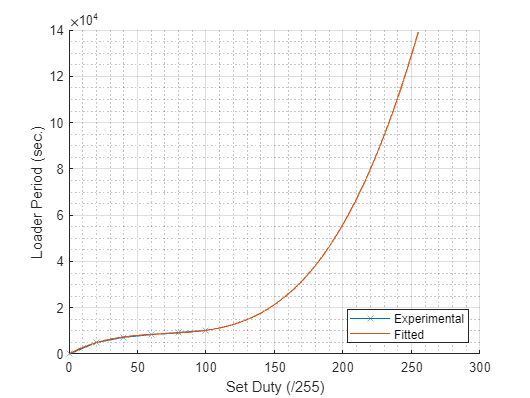


theoDuties = 0:1:255;
theoPeriods = polyval(fittedPoly, theoDuties);

figure()
hold on
grid on
grid minor
plot(duties, periods, "x-")
plot(theoDuties, theoPeriods)
xlabel("Set Duty (/255)")
ylabel("Loader Period (sec.)")
legend("Experimental", "Fitted", Location="southeast")
hold off
saveas(gcf, "graph_duty.png")

syms x y
y = poly2sym(fittedPoly)

$$y = \frac{283\,x^{3}}{14400}-\frac{691\,x^{2}}{168}+\frac{79823\,x}{252}+\frac{2647205138112211}{70368744177664}$$

finv = matlabFunction(finverse(y))

finv = function_handle with value:
    @(x)1.0./(x.*2.54416961130742e+1+sqrt((x.*2.54416961130742e+1-2.236410629423209e+5).^2+1.29348497368856e+8)-2.236410629423209e+5).^(1.0./3.0).*(-5.057320329772584e+2)+(x.*2.54416961130742e+1+sqrt((x.*2.54416961130742e+1-2.236410629423209e+5).^2+1.29348497368856e+8)-2.236410629423209e+5).^(1.0./3.0)+6.976274608783443e+1


finv(9000)

ans =     76.5851e+000


getDuty = finv

getDuty = function_handle with value:
    @(x)1.0./(x.*2.54416961130742e+1+sqrt((x.*2.54416961130742e+1-2.236410629423209e+5).^2+1.29348497368856e+8)-2.236410629423209e+5).^(1.0./3.0).*(-5.057320329772584e+2)+(x.*2.54416961130742e+1+sqrt((x.*2.54416961130742e+1-2.236410629423209e+5).^2+1.29348497368856e+8)-2.236410629423209e+5).^(1.0./3.0)+6.976274608783443e+1


% fittedPolyInverse = polyfit(rpms, thousands, 3)
% theoRpms = 0:50:10e3
% theoThosands = polyval(fittedPolyInverse, theoRpms)
% figure()
% hold on
% grid on
% grid minor
% plot(thousands, rpms, "x-")
% plot(theoThosands, theoRpms)
% xlabel("Set Duty (/1000)")
% ylabel("Motor RPM")
% legend("Experimental", "Fitted", Location="southeast")
% hold off
% saveas(gcf, "graph_duty_thosand_inverse.png")